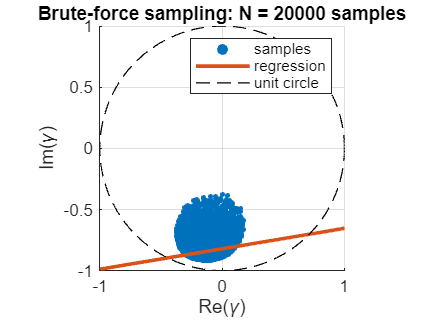

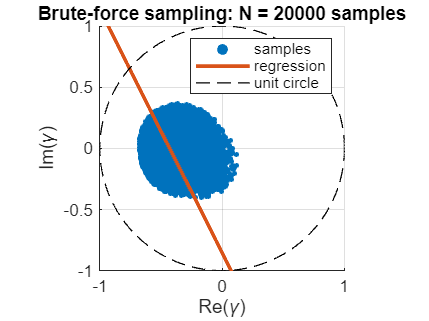

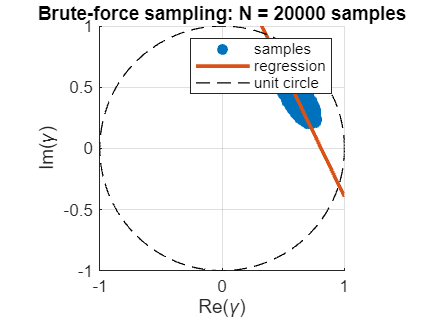

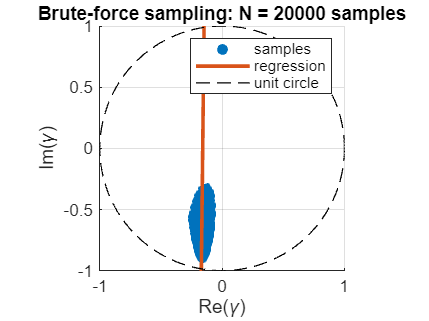

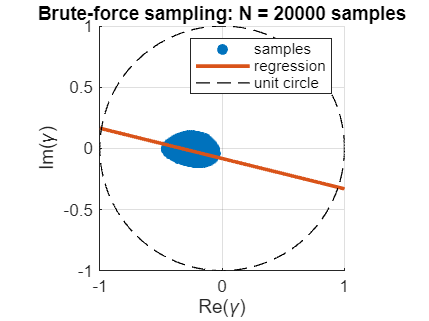

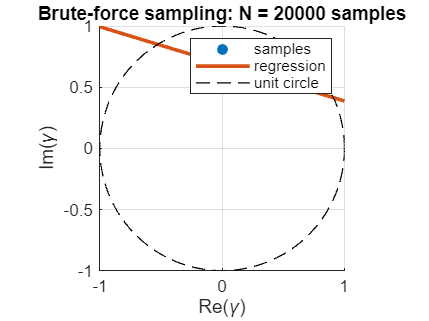

clear;

fileNames = ["data/c3x7_s1602_l48.m","data/c3x7_s1794_l290.m","data/c3x7_s1914_l275.m","data/c7x17_s1602_l48.m","data/c7x17_s1794_l290.m","data/c7x17_s1914_l275.m"];
P_values = zeros(6, 2);
N = 20000;
for l=1:6

fileName = fileNames(l);

gamma_vals = BruteForce(fileName, N);

P = linortfit(real(gamma_vals), imag(gamma_vals));
P_values(l, :) = P;

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
hold on;
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled'); 
x = linspace(-1, 1, 100);
plot(x,P(1)+P(2)*x, 'LineWidth', 2);
axis equal; grid on;
xlabel('Re(\gamma)'); ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));
% draw unit circle for reference
 
th = linspace(0,2*pi,500); plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
legend('samples','regression' ,'unit circle');
xlim([-1 1]);
ylim([-1 1]);

hold off;

end


writematrix(P_values, "BruteForce_OR_values");
